## Read Race Laptime Data

Monaco_Race = readtable('Laptime CSV Data/2023 Season/MonacoGP/2023 Monaco LapTimes.csv');

## Create Visualisations for Race Strategy and Times

Plotting the laptimes and trends for the top 3 finishers.

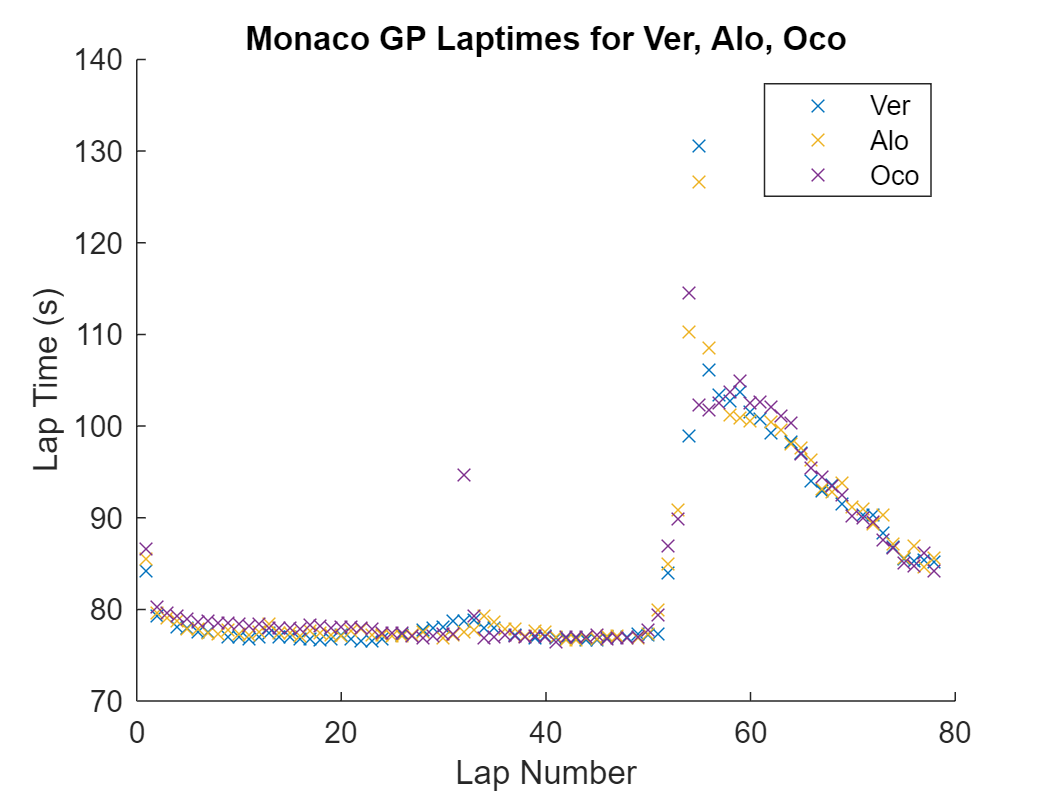

MV_laptimes = table2array(Monaco_Race(:,3));
FA_laptimes = table2array(Monaco_Race(:,5));
EO_laptimes = table2array(Monaco_Race(:,7));

lap_number = 1:78;
race_laptimes = [MV_laptimes FA_laptimes EO_laptimes];

scatter(lap_number,race_laptimes,'x')
colororder(["#0072BD"; "#EDB120"; "#7E2F8E"])
title("Monaco GP Laptimes for Ver, Alo, Oco")
xlabel("Lap Number")
ylabel("Lap Time (s)")
legend(["Ver" "Alo" "Oco"])

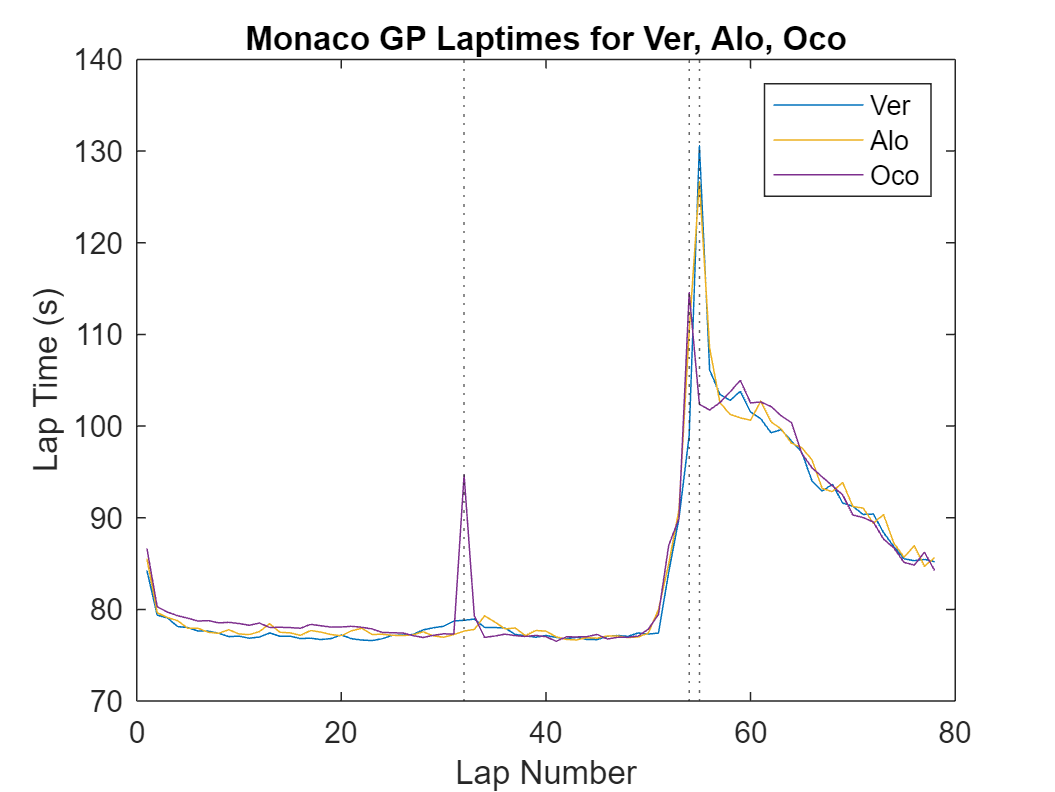


plot(lap_number,race_laptimes)
xline([32, 54, 55],":")
colororder(["#0072BD"; "#EDB120"; "#7E2F8E"])
title("Monaco GP Laptimes for Ver, Alo, Oco")
xlabel("Lap Number")
ylabel("Lap Time (s)")
legend(["Ver" "Alo" "Oco"])

Plotting the delta to Verstappen for FA and EO.

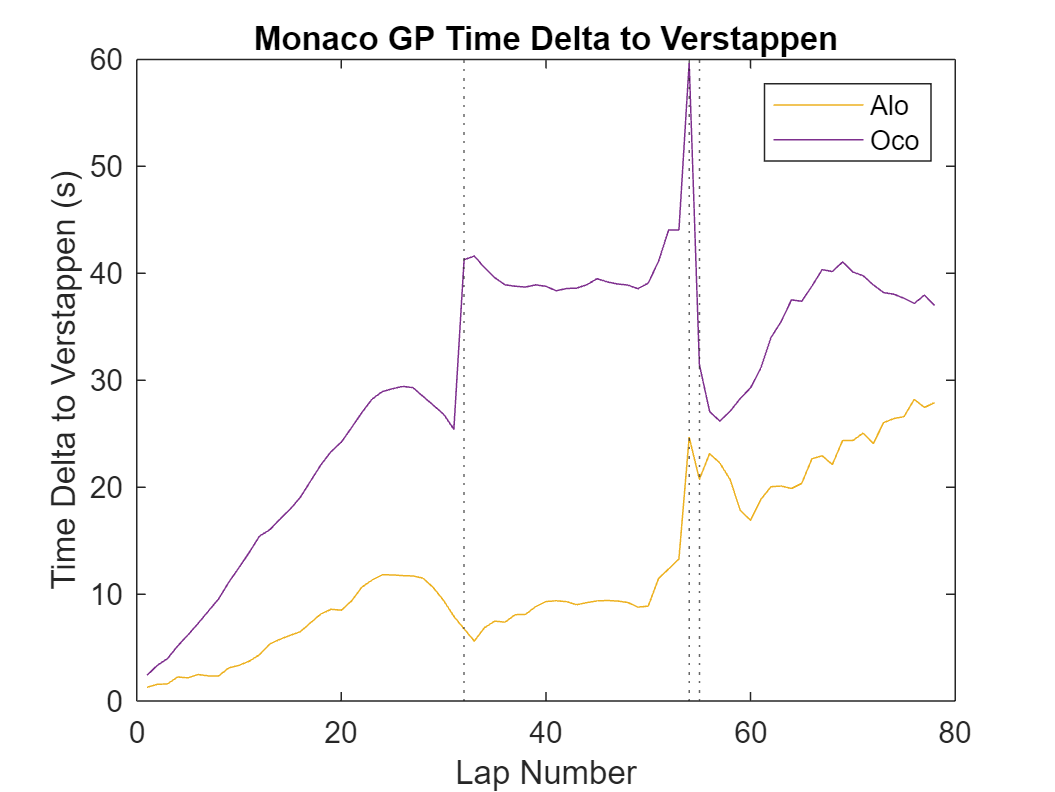

FA_raceDelta2Ver = table2array(Monaco_Race(:,10));
EO_raceDelta2Ver = table2array(Monaco_Race(:,12));

raceDelta2Ver = [FA_raceDelta2Ver, EO_raceDelta2Ver];

plot(lap_number,raceDelta2Ver)
title("Monaco GP Time Delta to Verstappen")
xlabel("Lap Number")
ylabel("Time Delta to Verstappen (s)")
colororder(["#EDB120"; "#7E2F8E"])
xline([32, 54, 55],":")
legend(["Alo" "Oco"])